Postupne vyplneni ukolu v 6. zadani

close all
clear all
clc


1) Znázornění chování normy vektoru rychlostí kloubových souřadnic

%nastaveni promennych pro nasledujici vypocet homogennich transformacnich
%matic v domovske poloze manipulatoru
di = [0,0,0]; %posuny v ose Z
Thetai = [0,0,0]; %rotace kolem osy Z
ai = [2,1.5,0.5]; %posun v ose X (delky ramen manipulatoru)
alphai = [0,0,0]; %rotace kolem X

T_1_0 = transf(di(1),Thetai(1),ai(1),alphai(1));
T_2_1 = transf(di(2),Thetai(2),ai(2),alphai(2));
T_3_2 = transf(di(3),Thetai(3),ai(3),alphai(3));

%nastaveni promennych pro simulaci
t = 10;
vmax = 1;
a = 0;
smax = 3.9769;
pocetVzorku = 100;
s = linspace(0,smax,pocetVzorku);
phi = linspace(-0.5,pi/2,pocetVzorku);
dQnorm = zeros(pocetVzorku);
dQnorm_lin = zeros(pocetVzorku);

Ukol 1

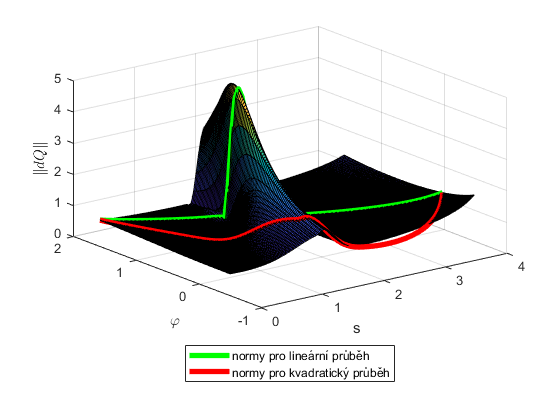

for i=1:pocetVzorku
    phi_i = phi(i);
    for j=1:pocetVzorku
        s_t = s(j);
        MCSstar = GENtraj(s_t,vmax,a,phi_i,2);
        ACS = IOKU(ai,MCSstar);
        dQnorm(i,j)=norm(ACS(:,2));
    end
end
figure()
surf(s,phi,dQnorm)
xlabel("s")
ylabel("$\varphi$",'interpreter','latex')
zlabel("$\Vert dQ \Vert$", 'Interpreter',"latex")

set(gcf,'Renderer','Painter');
saveas(gcf,'6_Graphics/Norma_vekt_dQ_konst','epsc')%vektor pro pdf
saveas(gcf,'6_Graphics/Norma_vekt_dQ_konst','png')%pro zobrazeni
hold on

clear i j
phi_lin_prubeh = zeros(pocetVzorku,3);
phi_quad_prubeh = zeros(pocetVzorku,3);
for i=1:pocetVzorku
    s_t = s(i);
    MCSstar_linear = GENtraj(s_t,vmax,a,pi/2,0); %generovani trajektorie s linearnim pohybem konc. ef
    MCSstar_quadratic = GENtraj(s_t,vmax,a,pi/2,1); %generovani trajektorie s kvadratickym pohybem konc. ef
    phi_linear = MCSstar_linear(3,1); %natoceni konc. ef. v linearnim prubehu v case s_t
    phi_quadratic = MCSstar_quadratic(3,1); %natoceni konc. ef. v kvadratickem prubehu v case s_t
    MCSstar_linear_t = GENtraj(s_t,vmax,a,phi_linear,2);
    MCSstar_quadratic_t = GENtraj(s_t,vmax,a,phi_quadratic,2);
    ACS_linear = IOKU(ai,MCSstar_linear_t);
    ACS_quadratic = IOKU(ai,MCSstar_quadratic_t);
    dQnorm_linear_t=norm(ACS_linear(:,2));
    dQnorm_quadratic_t =norm(ACS_quadratic(:,2));
    phi_lin_prubeh(i,:) = [s_t,phi_linear,dQnorm_linear_t];
    phi_quad_prubeh(i,:) = [s_t,phi_quadratic,dQnorm_quadratic_t];
end

plot3(phi_lin_prubeh(:,1),phi_lin_prubeh(:,2),phi_lin_prubeh(:,3),'LineWidth',4,'Color','green')
legend('','normy pro lineární průběh','Location',"southoutside")
saveas(gcf,'6_Graphics/Norma_vekt_dQ_lin3D','epsc')%vektor pro pdf
saveas(gcf,'6_Graphics/Norma_vekt_dQ_lin3D','png')%pro zobrazeni
plot3(phi_quad_prubeh(:,1),phi_quad_prubeh(:,2),phi_quad_prubeh(:,3),'LineWidth',4,'Color','red')
legend('','normy pro lineární průběh','normy pro kvadratický průběh','Location',"southoutside")
saveas(gcf,'6_Graphics/Norma3d_vekt_dQ_vse','epsc')%vektor pro pdf
saveas(gcf,'6_Graphics/Norma3d_vekt_dQ_vse','png')%pro zobrazeni

Simulace pri konstantnim uhlu phi

% phiS = 0;
% type = 2;
% out_konst = sim('manipulator');

%pozice, kdy manipulator dokoncil pohyb
% endPosition = find(out_konst.simout.Data(:,22:24)==0,1);%nulova rychlost-->konec pohybu

% % vypocet norem vektoru rychlosti pro jednotlive casove okamziky
% dQ = out_konst.simout.Data(:,end-14:end-12);%vektor rychlosti
% traj = out_konst.simout.Data(:,end-8:end-6);%naplanovana poloha konc efektoru
% dQnorm = zeros(length(dQ(:,1)));%norma vektoru rychlosti
% for i = (1:1:length(dQ(:,1)))
%     dQnorm(i) = norm(dQ(i,:));
% end
% 
% figure()
% subplot(2,1,1)
% plot(out_konst.simout.Time(1:endPosition),traj(1:endPosition,3))
% legend('$\varphi$','Location','northwest','Interpreter','latex')
% title('Prubeh uhlu koncoveho efektoru.')
% xlabel('s [m]')
% ylabel('\phi [rad]')
% 
% subplot(2,1,2)
% plot(out_konst.simout.Time(1:endPosition),dQnorm(1:endPosition))
% legend('||d\Theta||','Location','northwest')
% title('Prubeh normy vektoru rychlosti kloubovych souradnic.')
% xlabel('s [m]')
% ylabel('||d\Theta|| [rad/s]')
% 
% %ulozeni grafu
% saveas(gcf,'6_Graphics/Norma_vekt_dQ_konst','epsc')%vektor pro pdf
% saveas(gcf,'6_Graphics/Norma_vekt_dQ_konst','png')%pro zobrazeni


Simulace pro linearni prubeh uhlu

phiS = pi/2;
type = 0;
out_lin = sim('manipulator');

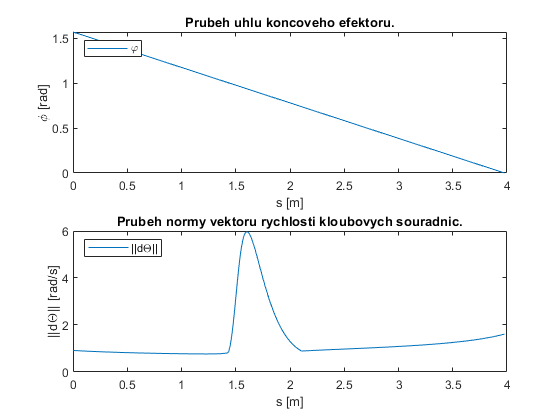


%pozice, kdy manipulator dokoncil pohyb
endPosition = find(out_lin.simout.Data(:,22:24)==0,1)-1;%nulova rychlost-->konec pohybu

% vypocet norem vektoru rychlosti pro jednotlive casove okamziky
dQ = out_lin.simout.Data(:,end-14:end-12);%vektor rychlosti
traj = out_lin.simout.Data(:,end-8:end-6);%naplanovana poloha konc efektoru
dQnorm = zeros(length(dQ(:,1)));%norma vektoru rychlosti
for i = (1:1:length(dQ(:,1)))
    dQnorm(i) = norm(dQ(i,:));
end

figure()
subplot(2,1,1)
plot(out_lin.simout.Time(1:endPosition),traj(1:endPosition,3))
legend('$\varphi$','Location','northwest','Interpreter','latex')
title('Prubeh uhlu koncoveho efektoru.')
xlabel('s [m]')
ylabel('\phi [rad]')

subplot(2,1,2)
plot(out_lin.simout.Time(1:endPosition),dQnorm(1:endPosition))
legend('||d\Theta||','Location','northwest')
title('Prubeh normy vektoru rychlosti kloubovych souradnic.')
xlabel('s [m]')
ylabel('||d\Theta|| [rad/s]')

%ulozeni grafu
saveas(gcf,'6_Graphics/Norma_vekt_dQ_lin','epsc')%vektor pro pdf
saveas(gcf,'6_Graphics/Norma_vekt_dQ_lin','png')%pro zobrazeni

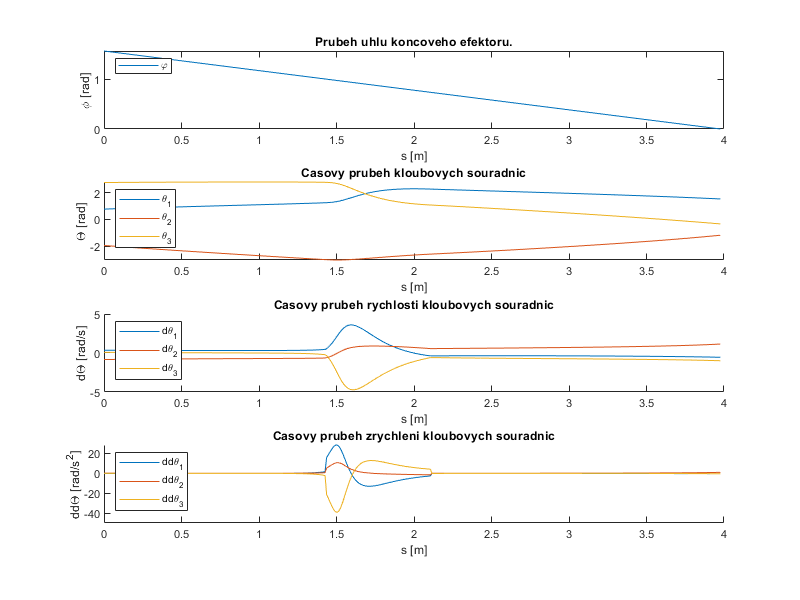


%casove prubehy kloubovych souradnic
f = figure();
f.Position(3:4) = [800,600];
hold on
Q = out_lin.simout.Data(:,end-17:end-15);
dQ = out_lin.simout.Data(:,end-14:end-12);
ddQ = out_lin.simout.Data(:,end-11:end-9);

subplot(4,1,1)
plot(out_lin.simout.Time(1:endPosition),traj(1:endPosition,3))
legend('$\varphi$','Location','northwest','Interpreter','latex')
title('Prubeh uhlu koncoveho efektoru.')
xlabel('s [m]')
ylabel('\phi [rad]')

subplot(4,1,2)
hold on
plot(out_lin.simout.Time(1:endPosition),Q(1:endPosition,:))
legend('\theta_1','\theta_2','\theta_3','Location','northwest')
title('Casovy prubeh kloubovych souradnic')
xlabel('s [m]')
ylabel('\Theta [rad]')

subplot(4,1,3)
hold on
plot(out_lin.simout.Time(1:endPosition),dQ(1:endPosition,:))
legend('d\theta_1','d\theta_2','d\theta_3','Location','northwest')
title('Casovy prubeh rychlosti kloubovych souradnic')
xlabel('s [m]')
ylabel('d\Theta [rad/s]')

subplot(4,1,4)
hold on
plot(out_lin.simout.Time(1:endPosition),ddQ(1:endPosition,:))
legend('dd\theta_1','dd\theta_2','dd\theta_3','Location','northwest')
title('Casovy prubeh zrychleni kloubovych souradnic')
xlabel('s [m]')
ylabel('dd\Theta [rad/s^2]')

%ulozeni figure
saveas(gcf,'6_Graphics/Kloub_souradnice_lin','epsc')%vektor pro pdf
saveas(gcf,'6_Graphics/Kloub_souradnice_lin','png')%pro zobrazeni

Kvadraticka interpolace

phiS = pi/2;
type = 1;
out_quad = sim('manipulator');

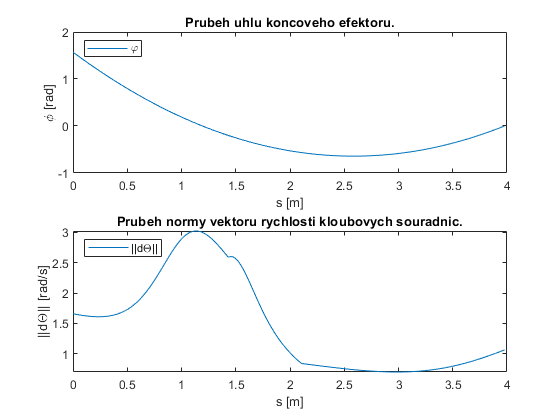


%pozice, kdy manipulator dokoncil pohyb
endPosition = find(out_quad.simout.Data(:,22:24)==0,1)-1;%nulova rychlost-->konec pohybu

% vypocet norem vektoru rychlosti pro jednotlive casove okamziky
dQ = out_quad.simout.Data(:,end-14:end-12);%vektor rychlosti
traj = out_quad.simout.Data(:,end-8:end-6);%naplanovana poloha konc efektoru
dQnorm = zeros(length(dQ(:,1)));%norma vektoru rychlosti
for i = (1:1:length(dQ(:,1)))
    dQnorm(i) = norm(dQ(i,:));
end

figure()
subplot(2,1,1)
plot(out_quad.simout.Time(1:endPosition),traj(1:endPosition,3))
legend('$\varphi$','Location','northwest','Interpreter','latex')
title('Prubeh uhlu koncoveho efektoru.')
xlabel('s [m]')
ylabel('\phi [rad]')

subplot(2,1,2)
plot(out_quad.simout.Time(1:endPosition),dQnorm(1:endPosition))
legend('||d\Theta||','Location','northwest')
title('Prubeh normy vektoru rychlosti kloubovych souradnic.')
xlabel('s [m]')
ylabel('||d\Theta|| [rad/s]')

%ulozeni grafu
saveas(gcf,'6_Graphics/Norma_vekt_dQ_quad','epsc')%vektor pro pdf
saveas(gcf,'6_Graphics/Norma_vekt_dQ_quad','png')%pro zobrazeni

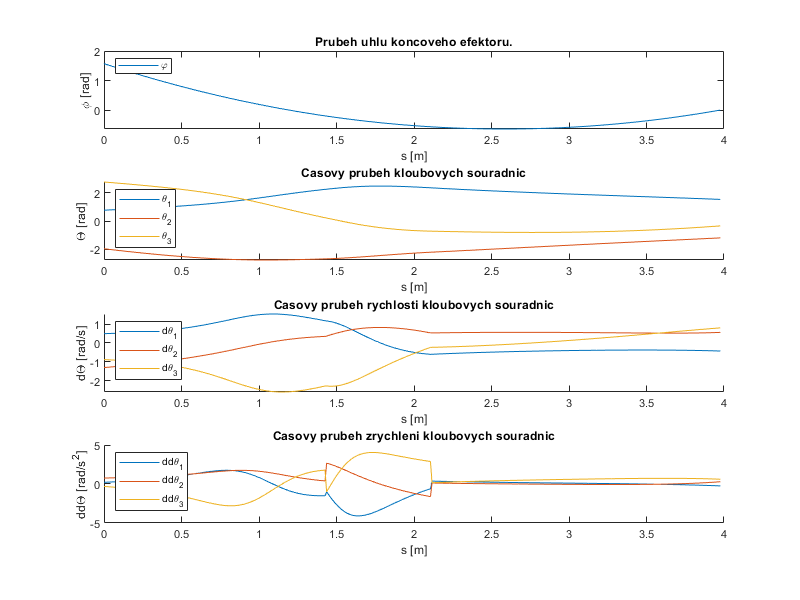


%casove prubehy kloubovych souradnic
f = figure();
f.Position(3:4) = [800,600];
hold on
Q = out_quad.simout.Data(:,end-17:end-15);
dQ = out_quad.simout.Data(:,end-14:end-12);
ddQ = out_quad.simout.Data(:,end-11:end-9);

subplot(4,1,1)
plot(out_quad.simout.Time(1:endPosition),traj(1:endPosition,3))
legend('$\varphi$','Location','northwest','Interpreter','latex')
title('Prubeh uhlu koncoveho efektoru.')
xlabel('s [m]')
ylabel('\phi [rad]')

subplot(4,1,2)
hold on
plot(out_quad.simout.Time(1:endPosition),Q(1:endPosition,:))
legend('\theta_1','\theta_2','\theta_3','Location','northwest')
title('Casovy prubeh kloubovych souradnic')
xlabel('s [m]')
ylabel('\Theta [rad]')

subplot(4,1,3)
hold on
plot(out_quad.simout.Time(1:endPosition),dQ(1:endPosition,:))
legend('d\theta_1','d\theta_2','d\theta_3','Location','northwest')
title('Casovy prubeh rychlosti kloubovych souradnic')
xlabel('s [m]')
ylabel('d\Theta [rad/s]')

subplot(4,1,4)
hold on
plot(out_quad.simout.Time(1:endPosition),ddQ(1:endPosition,:))
legend('dd\theta_1','dd\theta_2','dd\theta_3','Location','northwest')
title('Casovy prubeh zrychleni kloubovych souradnic')
xlabel('s [m]')
ylabel('dd\Theta [rad/s^2]')

%ulozeni figure
saveas(gcf,'6_Graphics/Kloub_souradnice_quad','epsc')%vektor pro pdf
saveas(gcf,'6_Graphics/Kloub_souradnice_quad','png')%pro zobrazeni

pomocne funkce

%funkce pro vypocet transformacni matice z jednoho s.s. do druheho

function Tn = transf(d,Theta, a, alpha)
    %translace v ose Z
    TtransZ = eye(4);
    TtransZ(3,4) = d;
    %rotace kolem osy Z
    TrotZ = zeros(4,4);
    TrotZ(1:3,1:3) = [cos(Theta),-sin(Theta),0;
                      sin(Theta),cos(Theta) ,0;
                     0          ,0           ,1];
    TrotZ(4,4) = 1;
    
    %translace v ose X
    TtransX = eye(4);
    TtransX(1,4) = a;
    %rotace kolem osy X
    TrotX = zeros(4,4);
    TrotX(1:3,1:3) = [1,          0,           0;
                    0,cos(alpha),-sin(alpha);
                    0,sin(alpha),cos(alpha)];
    TrotX(4,4) = 1;
    %vypocet homogenni transformacni matice z n-1 do nteho s.s.
    Tn = TtransZ*TrotZ*TtransX*TrotX;
end